# Дополнительное задание по лабораторной работе №4

Вы синтезировали контур скорости в п.4 с учетом того, что контур тока был настроен на линейный оптимум. Настройте, контур тока на биноминальный оптимум и перенастройте контур скорости с учетом этого. Пришлите коэффициенты ПД-регулятора скорости. Постройте график переходного процесса

Загрузка данных

load('data.mat')

### Синтез регулятора

Расчет ПИ регулятора тока

syms Tt s L R
Wia_spml = 1/(L*s+R);
wol = 1/(3*Tt*s*(Tt*s+1))

$$wol = \frac{1}{3\,\mathrm{Tt}\,s\,\left(\mathrm{Tt}\,s+1\right)}$$

wreg = wol/Wia_spml;
disp(collect(wreg, s))

$$\frac{L\,s+R}{\left(3\,{\mathrm{Tt}}^{2}\right)\,s^{2}+\left(3\,\mathrm{Tt}\right)\,s}$$

syms Kpa Kia
Kpa = L/3/Tt;
Kia = R/3/Tt;
wreg_t = (Kpa+Kia/s)/(Tt*s+1);
disp(collect(wreg_t, s))

$$\frac{L\,s+R}{\left(3\,{\mathrm{Tt}}^{2}\right)\,s^{2}+\left(3\,\mathrm{Tt}\right)\,s}$$

Tt = 0.005;

crl.Kpa = ob.L/3/Tt

crl = struct with fields:
    Kpa: 1.5098
    Kia: 721.7834


crl.Kia = ob.R/3/Tt;
kdw = 180/pi;
Tmdl = 0.1;

syms Tu Tt s Ce J

коэффициент датчика скорости

syms kdw
Wcrl = 1/(3*Tt*s+1)

$$Wcrl = \frac{1}{3\,\mathrm{Tt}\,s+1}$$

Wob2 = Ce*kdw/(J*s)

$$Wob2 = \frac{\mathrm{Ce}\,\mathrm{kdw}}{J\,s}$$

передаточная функция раз. системы, настроенный на биноминальный оптиум

disp(simplify(collect(Wcrl*Wob2,s)))

$$\frac{\mathrm{Ce}\,\mathrm{kdw}}{J\,s\,\left(3\,\mathrm{Tt}\,s+1\right)}$$

wol = 1/(3*Tu*s*(Tu*s+1));
Wreg = wol/(Wcrl*Wob2);
disp(simplify(collect(Wreg, s)))

$$\frac{J\,\left(3\,\mathrm{Tt}\,s+1\right)}{3\,\mathrm{Ce}\,\mathrm{Tu}\,\mathrm{kdw}\,\left(\mathrm{Tu}\,s+1\right)}$$

Проверка формул коэффициентов

syms kdw J Kg Tu Kda Kpa Tt s Tur Ki Kp
Kg = J/(3*Ce*Tu*kdw)

$$Kg = \frac{J}{3\,\mathrm{Ce}\,\mathrm{Tu}\,\mathrm{kdw}}$$

Аналоговый ПДД

Kda = Kg*3*Tt

$$Kda = \frac{J\,\mathrm{Tt}}{\mathrm{Ce}\,\mathrm{Tu}\,\mathrm{kdw}}$$

Kpa = Kg*1

$$Kpa = \frac{J}{3\,\mathrm{Ce}\,\mathrm{Tu}\,\mathrm{kdw}}$$

simplify((Kda*s+Kpa)/(Tu*s+1))

$$ans = \frac{J\,\left(3\,\mathrm{Tt}\,s+1\right)}{3\,\mathrm{Ce}\,\mathrm{Tu}\,\mathrm{kdw}\,\left(\mathrm{Tu}\,s+1\right)}$$


$$\frac{J\,{\left(3\,\mathrm{Tt}\,s+1\right)}}{3\,\mathrm{Ce}\,\mathrm{Tu}\,\mathrm{kdw}\,{\left(\mathrm{Tu}\,s+1\right)}}$$


### Моделирование

crl.Tt = 0.0001;

crl.Kpa = ob.L/3/crl.Tt;
crl.Kia = ob.R/3/crl.Tt;

spl.Tu = crl.Tt;
kdw = 180/pi;
Tmdl = 1;
To = 0.1*crl.Tt;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur;

spl.Kg = ob.J/(3*ob.Ce*spl.Tu*kdw)

spl = struct with fields:
       Tu: 5.0000e-06
      Tur: 5.0000e-06
       Kg: 5.3495e+04
      Kda: 32.0969
      Kpa: 2.1398e+04
    Kd2dg: 1.2520e+06
    Kp2dg: 2.1398e+04


Аналоговый ПД

spl.Kda = 3*spl.Kg*crl.Tt;%аналогавая система
spl.Kpa = spl.Kg*1;

Цифровой  ПД

spl.Kd2dg = 3*spl.Kg*1/(exp(To/crl.Tt)-1);%решение задачи на переходный процесс в апереоическом звене, 
% данные коэффициенты позволяют компенсировать Д-звено
spl.Kp2dg = spl.Kg*1;

Построение графиков переходных процессов

warning off
Tmdl=0.1;
simNew = sim('lab4_2_1.slx', 'ReturnWorkspaceOutputs','on')

simNew =   Simulink.SimulationOutput:

                   tout: [1000001x1 double] 
                      w: [1000001x5 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

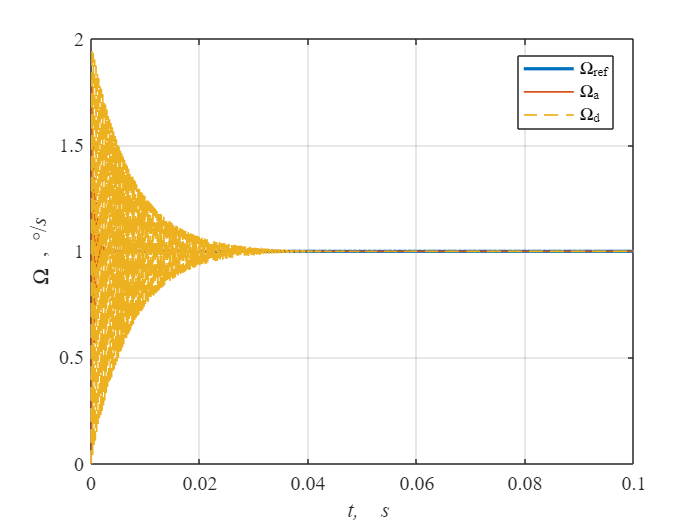


h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 2)
hold on
grid on
plot(t,wa,'Linewidth', 1, 'LineStyle','-')
plot(t,wd,'Linewidth', 1, 'LineStyle','--')
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

C запаздыванием

spl.Tur = 0.5*To;
spl.Tz = 1.5*To;

spl.Tu = spl.Tur+spl.Tz;

spl.Kg = ob.J/(3*ob.Ce*spl.Tu*kdw)

spl = struct with fields:
       Tu: 2.0000e-05
      Tur: 5.0000e-06
       Kg: 1.3374e+04
      Kda: 4.0121
      Kpa: 1.3374e+04
    Kd2dg: 3.8148e+05
    Kp2dg: 1.3374e+04
       Tz: 1.5000e-05


Аналоговый ПД

spl.Kda = 3*spl.Kg*crl.Tt;%аналогавая система
spl.Kpa = spl.Kg*1;

Цифровой  ПД

spl.Kd2dg = 3*spl.Kg*1/(exp(To/crl.Tt)-1);%решение задачи на переходный процесс в апереоическом звене, 
% данные коэффициенты позволяют компенсировать Д-звено
spl.Kp2dg = spl.Kg*1;
warning off
Tmdl=0.005;
simNew = sim('lab4_2_1_1.slx', 'ReturnWorkspaceOutputs','on')

simNew =   Simulink.SimulationOutput:

                   tout: [50001x1 double] 
                      w: [50001x5 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

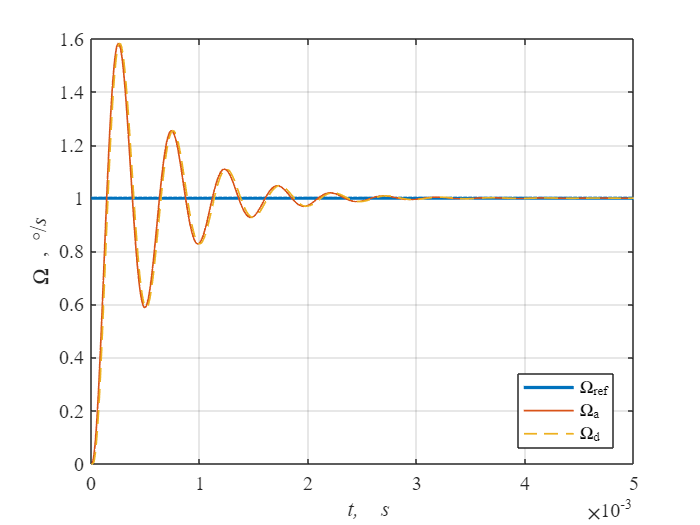


h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 2)
hold on
grid on
plot(t,wa,'Linewidth', 1, 'LineStyle','-')
plot(t,wd,'Linewidth', 1, 'LineStyle','--')
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')